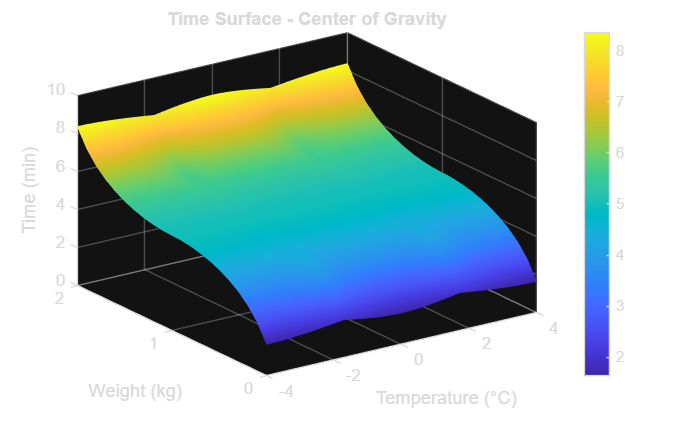

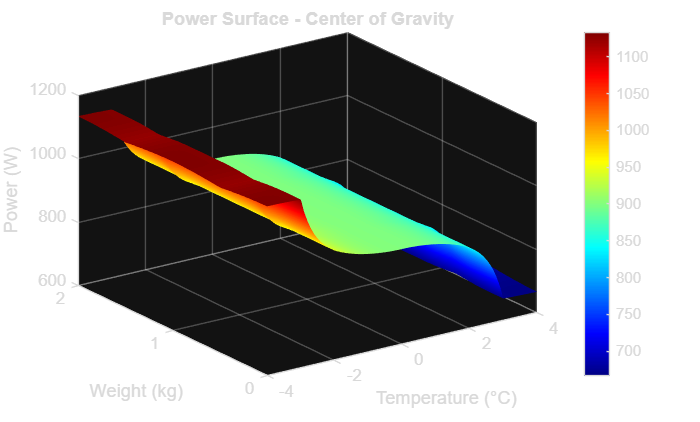

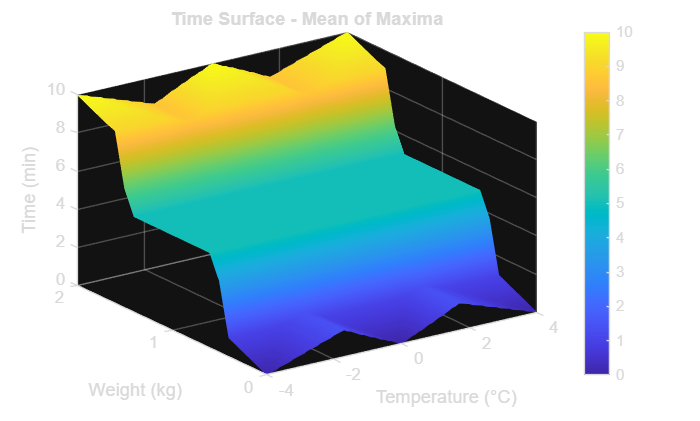

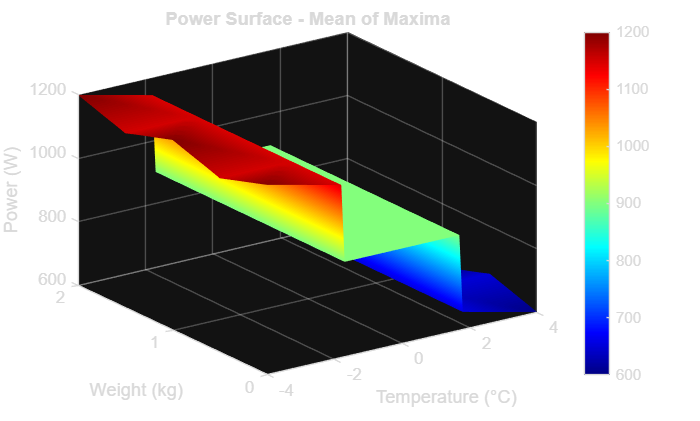

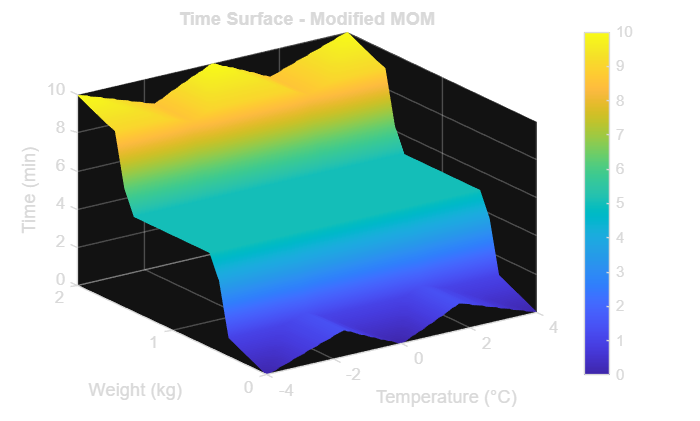

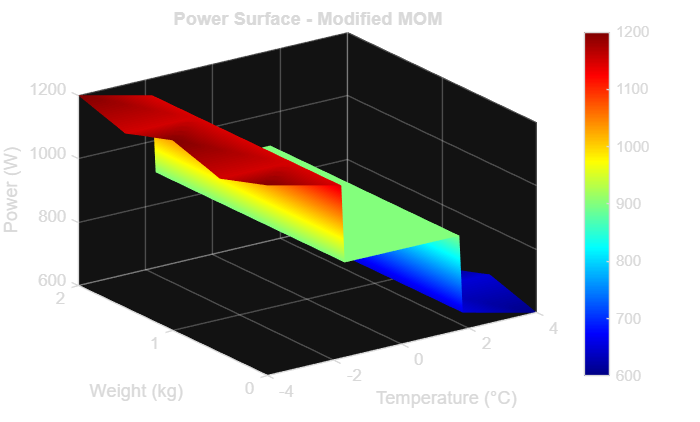

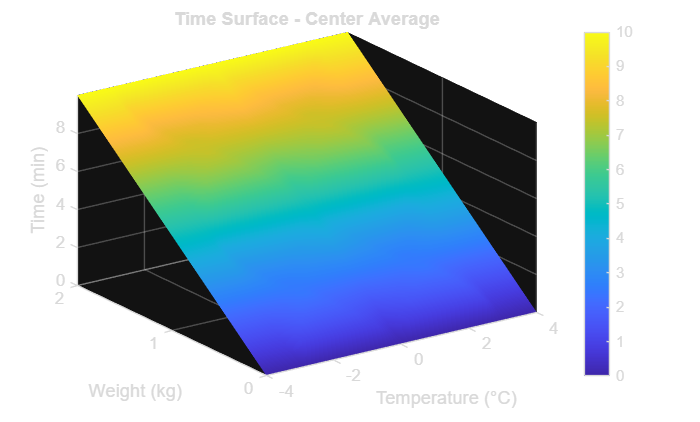

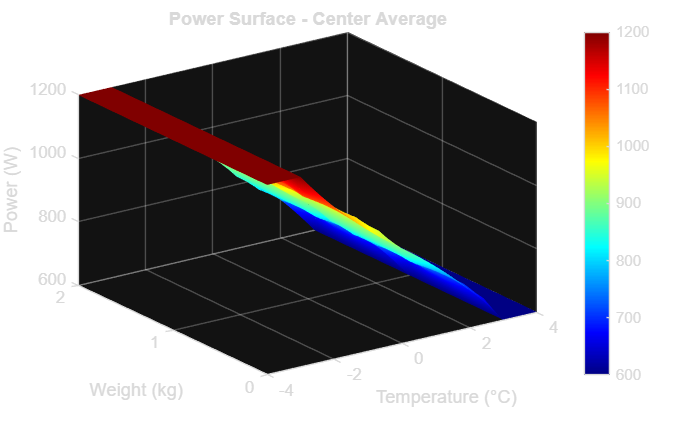

clear; clc; close all;
% 1. Output folder
output_dir = 'fuzzy_3d_outputs';
if ~exist(output_dir,'dir')
    mkdir(output_dir);
end
% 2. Universe
x_domain = -4:0.1:4;
y_domain = 0:0.1:2;
z_domain = 0:0.1:10;
w_domain = 600:1:1200;
methods = {'cog','mom','modified_mom','center_average'};
titles  = {'Center of Gravity','Mean of Maxima','Modified MOM','Center Average'};
% 3. Run simulation grid
[X,Y] = meshgrid(x_domain,y_domain);
for m = 1:length(methods)
    method = methods{m};
    Z = zeros(size(X));
    W = zeros(size(X));
    for i = 1:size(X,1)
        for j = 1:size(X,2)
            [z_out,w_out] = infer_one_point(X(i,j),Y(i,j),method,z_domain,w_domain);
            Z(i,j) = z_out;
            W(i,j) = w_out;
        end
    end
    % 🔥 Z Surface (Time)
    fig1 = figure('Color','w');
    surf(X,Y,Z,'EdgeColor','none');   % smoother surface
    colormap(parula);
    colorbar;
    title(['Time Surface - ' titles{m}]);
    xlabel('Temperature (°C)');
    ylabel('Weight (kg)');
    zlabel('Time (min)');
    view([-35 30]);
    grid on;
    shading interp;
    saveas(fig1, fullfile(output_dir,['Z_' methods{m} '.png']));
    % 🔥 W Surface (Power)
    fig2 = figure('Color','w');
    surf(X,Y,W,'EdgeColor','none');
    colormap(jet);
    colorbar;
    title(['Power Surface - ' titles{m}]);
    xlabel('Temperature (°C)');
    ylabel('Weight (kg)');
    zlabel('Power (W)');
    view([-35 30]);
    grid on;
    shading interp;
    saveas(fig2, fullfile(output_dir,['W_' methods{m} '.png']));

end
disp('✅ 完成：所有 fuzzy surface 已輸出（CA 保留原版本）');

✅ 完成：所有 fuzzy surface 已輸出（CA 保留原版本）


% 4. Inference (UNCHANGED ORIGINAL CA VERSION)
function [z_out, w_out] = infer_one_point(x0, y0, method, z_domain, w_domain)
    mu_x = [left_shoulder(x0,-4,0), trimf(x0,-3,0,3), right_shoulder(x0,0,4)];
    mu_y = [left_shoulder(y0,0,1),  trimf(y0,0,1,2),  right_shoulder(y0,1,2)];
    alpha = [
        min(mu_x(1), mu_y(3)), min(mu_x(1), mu_y(2)), min(mu_x(1), mu_y(1)), ...
        min(mu_x(2), mu_y(3)), min(mu_x(2), mu_y(2)), min(mu_x(2), mu_y(1)), ...
        min(mu_x(3), mu_y(3)), min(mu_x(3), mu_y(2)), min(mu_x(3), mu_y(1))
    ];
    z_centers = [10, 5, 0, 10, 5, 0, 10, 5, 0];
    w_centers = [1200, 1200, 1200, 900, 900, 900, 600, 600, 600];
    if strcmp(method, 'center_average')
        denom = sum(alpha);
        if denom == 0
            z_out = 5;
            w_out = 900;
            return;
        end
        z_out = sum(alpha .* z_centers) / denom;
        w_out = sum(alpha .* w_centers) / denom;
        return;
    end
    %% Mamdani aggregation
    z_agg = zeros(size(z_domain));
    w_agg = zeros(size(w_domain));
    z_sets = {right_shoulder(z_domain,5,10), trimf(z_domain,0,5,10), left_shoulder(z_domain,0,5)};
    w_sets = {right_shoulder(w_domain,1000,1200), trimf(w_domain,600,900,1200), left_shoulder(w_domain,600,800)};
    z_idx = [1,2,3,1,2,3,1,2,3];
    w_idx = [1,1,1,2,2,2,3,3,3];
    for k = 1:9
        z_agg = max(z_agg, min(alpha(k), z_sets{z_idx(k)}));
        w_agg = max(w_agg, min(alpha(k), w_sets{w_idx(k)}));
    end
    z_out = defuzzify_alg(z_domain, z_agg, method);
    w_out = defuzzify_alg(w_domain, w_agg, method);
end
% 5. Defuzzification
function val = defuzzify_alg(domain, mu, method)
    if sum(mu) == 0
        val = NaN;
        return;
    end
    switch method
        case 'cog'
            val = sum(domain .* mu) / sum(mu);
        case 'mom'
            max_mu = max(mu);
            idx = mu == max_mu;
            val = mean(domain(idx));
        case 'modified_mom'
            max_mu = max(mu);
            idx = find(mu == max_mu);
            val = (domain(idx(1)) + domain(idx(end))) / 2;
    end
end
% 6. Membership functions
function mu = trimf(x,a,b,c)
    mu = max(min((x-a)/(b-a),(c-x)/(c-b)),0);
    mu(x==b) = 1;
end
function mu = left_shoulder(x,a,b)
    mu = ones(size(x));
    mu(x > a & x < b) = (b - x(x > a & x < b)) / (b - a);
    mu(x >= b) = 0;
end
function mu = right_shoulder(x,a,b)
    mu = zeros(size(x));
    mu(x > a & x < b) = (x(x > a & x < b) - a) / (b - a);
    mu(x >= b) = 1;
end